opts = detectImportOptions('fxdata.csv');
T = readtable('fxdata.csv',opts);

X = T;
Xc = table2cell(X);
X_transposed = Xc';
A = X_transposed;
tickers = A(1,:);
data = A(2:378,:);
data = cell2mat(data);
data = fillmissing(data, "previous",1);

size_data = size(data);
log_daily = zeros(size_data(1) - 1, size_data(2));


% Compute the daily returns
for j =1:size_data(2)
    for i=1:size_data(1)-1
        log_daily(i,j) = log(data(i+1,j) / data(i,j));
    end
end

correlation = corrcoef(log_daily);
distances = zeros(size_data(2), size_data(2));

for j =1:size_data(2)
    for i=1:size_data(2)
        distances(i,j) = sqrt(2 * (1 - correlation(i,j)));
    end
end
tickers = string(tickers);
for i= 1:length(tickers)
    tickers(i) = erase(tickers(i), '/USD');
end

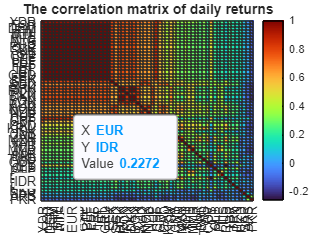

MeanCorrMatPerm=mean(correlation);
[sortedCorr, indPerm]=sort(MeanCorrMatPerm,'descend');
sorted = correlation(indPerm,indPerm);
sort_title= tickers(:,indPerm );

figure;
h = heatmap(sorted,"Colormap",turbo);
h.XDisplayLabels = string(sort_title);
h.YDisplayLabels = string(sort_title);
title("The correlation matrix of daily returns");

OutputNetwork(distances,tickers);

opts = detectImportOptions('country-currency.csv');
T_country = readtable('country-currency.csv',opts);
country = string(T_country.Country);
node_table = readtable("nodes.csv");
% Add location data to node table
node_table.Country = country;


% Output the node table
writetable(node_table,'nodes.csv','Delimiter',';');

OutputNetwork(correlation,tickers);